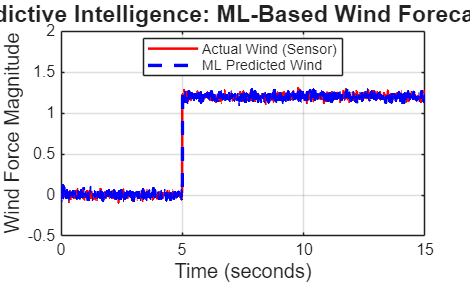

clc; clear; close all;

%% 1. Time Vector
t = 0:0.01:15;

%% 2. Create Wind Disturbance Signal (with realistic noise)
% Sudden gust at 5 seconds with random fluctuations
d = zeros(size(t));
d(t >= 5) = 1.2; 
noise = 0.03 * randn(size(t)); % Adds realism
d_noisy = d + noise;

%% 3. Prepare Data for ML (Time Series Lag)
% X (Input): Current wind value
% Y (Output): Next wind value (what we want to predict)
X = d_noisy(1:end-1)';
Y = d_noisy(2:end)';

%% 4. ML Implementation (Manual Linear Regression)
% Add a 'bias' column (intercept) to the input
X_bias = [ones(size(X)), X]; 

% Training: Solve for weights (beta) using the Normal Equation
% beta = (X'X)^-1 * X'Y
beta = (X_bias' * X_bias) \ (X_bias' * Y); 

% Prediction: Calculate the forecasted wind
predicted_d = X_bias * beta;

%% 5. Plotting the Results
figure('Color', 'w');
plot(t(2:end), Y, 'r', 'LineWidth', 1.5, 'DisplayName', 'Actual Wind (Sensor)');
hold on;
plot(t(2:end), predicted_d, 'b--', 'LineWidth', 2, 'DisplayName', 'ML Predicted Wind');

% Formatting for judges
grid on;
xlabel('Time (seconds)', 'FontSize', 12);
ylabel('Wind Force Magnitude', 'FontSize', 12);
title('Predictive Intelligence: ML-Based Wind Forecasting', 'FontSize', 14);
legend('Location', 'best');
axis([0 15 -0.5 2]); % Set clear view limits


% Display results in Command Window
fprintf('ML Model Training Complete.\n');

ML Model Training Complete.


fprintf('Learned Relationship: Wind(t+1) = %.4f + %.4f * Wind(t)\n', beta(1), beta(2));

Learned Relationship: Wind(t+1) = 0.0044 + 0.9954 * Wind(t)
